% https://mydailyengineering.wordpress.com/dry-steering/
% bilder av cad ligger i https://drive.google.com/drive/u/1/folders/1R42UJ85xGUDm-tD5RUjfcWQPFO0rt5rP
clc; clear; close all;


a_mesure = [55 52 60 63 58 61 57 54 58 53];
b_mesure = [152 156 154 152 155 153 154 157 155 153];

a_mm = mean(a_mesure) % mm kort side kontaktflate

a_mm =                       57.1


b_mm = mean(b_mesure) % mm Langside kontaktflate

b_mm =                      154.1



%a_mm = 55.67; 
%b_mm = 154; 
Fz_kg = 65.925; % kg vekt på hjulet (65.925 nytt) (80.575 gammelt)
sigma_deg = 7.98; % deg KPI
tau_deg = 6.18; % deg caster
r_dyn_mm = 203.2; % mm radius hjul hjul
CD_mm = 28.48; % mm   r_dyn * tan sigma
rs_mm = 10.05; % mm  skrubb radie, DO linja
delta_deg = linspace(-31, 31, 1000);   % deg styrevinkel
delta_deg2 = linspace(0,31,1000);

g = 9.81;         % m/s^2
a = a_mm*1e-3;    % m  
b = b_mm*1e-3;    % m
Fz = Fz_kg*g      % N

Fz =                  646.72425


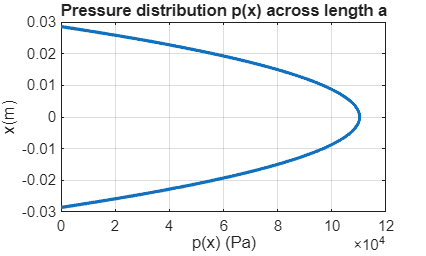

x = linspace(-a/2, a/2, 1000);   % m
sigma = deg2rad(sigma_deg); % rad
tau = deg2rad(tau_deg); % rad
r_dyn = r_dyn_mm*1e-3; % m
CD = CD_mm*1e-3; % m
rs = rs_mm*1e-3; % m
delta = deg2rad(delta_deg); % rad
delta2 = deg2rad(delta_deg2); %rad
m_t = r_dyn*tan(tau); % caster trail / mecanical trail
% Pressure Distribution
p = (6*Fz/(a^3*b)) .* (a/2 - x) .* (a/2 + x);  % Pa (N/m^2)

plot(p, x, 'LineWidth', 2)
grid on
xlabel('p(x) (Pa)')
ylabel('x(m)')
title('Pressure distribution p(x) across length a')

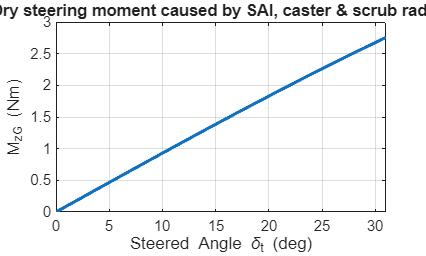


% Gravity based aligning moment
MzG = Fz * (rs + r_dyn*tan(sigma)) .* cos(sigma) .* sin(sigma) .* cos(tau) .* sin(delta2); % Nm
MzG = Fz * (rs + r_dyn*tan(sigma) + m_t) .* cos(sigma) .* sin(sigma) .* cos(tau) .* sin(delta2); % Nm

figure
plot(delta_deg2, MzG, 'LineWidth', 2)
grid on
xlabel('Steered Angle \delta_t (deg)')
ylabel('M_{zG} (Nm)')
title('Dry steering moment caused by SAI, caster & scrub radius')

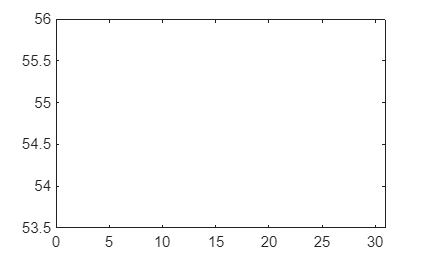


% Friction based moment
x0 = -a/2;
x1 = a/2;
y0 = -b/2; 
y1 = b/2; 

e0 = 24.03e-3; %m
beta = 10; %degrees

ex = e0*cosd(beta);
%ex = ex + trail; 
ey = e0*sind(beta);
mu = 1.75; %friction coeff

fun = @(x,y) ((6*Fz)/(a^3*b) .* (a/2 - x) .* (a/2 + x)).*(sqrt((ex - x).^2 + (ey - y).^2));

Mzft = mu * integral2(fun, x0, x1, y0, y1);

Mzf = Mzft*cos(sigma);%*cos(tau); %Nm

%Mzf = Mzf/1000; %Nm
Mfo = 0.4; %Nm
D = 40e-3; %m

Lk = 84.55e-3; %m
theta_tk = linspace(107.55, 84.17,1000); %degrees
theta_tk = deg2rad(theta_tk);
theta_rt = linspace(179.95,179.59,1000); %degrees
theta_rt = deg2rad(theta_rt);
theta_kk = deg2rad(68.54); %degrees
Frt = 1; %N ÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆ
R = D/2; %m
L = Lk .* sin(theta_tk);
Ftt = Frt .* cos(pi-theta_rt);
i = (Ftt .* L .* cos(theta_kk-(pi/2)))/(Frt .* R);

Mz = 2*((Mzf+MzG)./i) + Mfo

Mz =           29.3046491213661          29.3024632664728          29.3002827977584           29.298107712218          29.2959380068522          29.2937736786679          29.2916147246776          29.2894611419001          29.2873129273598          29.2851700780872          29.2830325911185          29.2809004634959          29.2787736922677          29.2766522744876          29.2745362072157          29.2724254875176          29.2703201124649          29.2682200791349          29.2661253846111          29.2640360259824          29.2619520003438           29.259873304796          29.2577999364457          29.2557318924052          29.2536691697926           29.251611765732          29.2495596773531          29.2475129017913          29.2454714361882          29.2434352776906          29.2414044234515          29.2393788706294          29.2373586163887          29.2353436578994          29.2333339923374          29.2313296168841          29.2293305287268          29.2273367250584       

max(Mz)

ans =           29.5116241374742


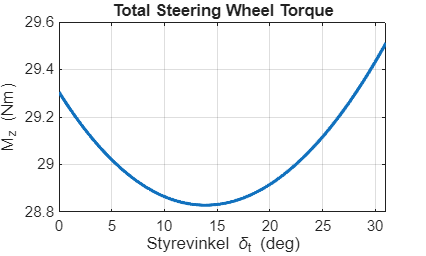

figure
plot(delta_deg2, Mz, 'LineWidth', 2)
grid on
xlabel('Styrevinkel \delta_t (deg)')
ylabel('M_{z} (Nm)')
title('Total Steering Wheel Torque')

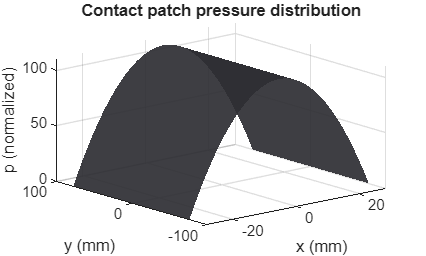


% 3D Pressure Distribution
x_vec = linspace(-a/2, a/2, 100);
y_vec = linspace(-b/2, b/2,  50);
[X, Y] = meshgrid(x_vec, y_vec);

P = (6*Fz / (a^3 * b)) .* (a/2 - X) .* (a/2 + X);

figure;
surf(X*1e3, Y*1e3, P*1e-3, ...
    'FaceColor', [0.18 0.18 0.20], ...
    'EdgeColor', 'none', ...
    'FaceAlpha', 0.92)

%daspect([1 1 1])
xlabel('x (mm)')
ylabel('y (mm)')
zlabel('p (normalized)')
title('Contact patch pressure distribution')
view([-40 25])